### 1 Theory

% 1
X = [1 2 3;4 5 6;7 8 9];
K = X;
conv2(X,K)

ans =      1     4    10    12     9
     8    26    56    54    36
    30    84   165   144    90
    56   134   236   186   108
    49   112   190   144    81


conv2(X,K,'valid')

ans = 165


% 2
% max-pooling
P1 = [5,6,12;8,9,4];
% MEAN-pooling
P2 = [3,13/4,4;-185/4,-190/4,-49];

% 3
% K should be identity matrix with dimension 1
%testing
conv2(X,eye(1))

ans =      1     2     3
     4     5     6
     7     8     9


## 2 CNN for LSE Classi�cation

Create the image

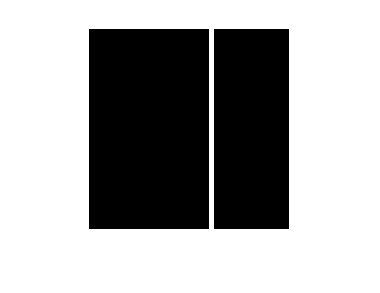

% class 0
images(:,:,1) = zeros(40);
images(:,25,1)=1;
% class 1
images(:,:,2) = ones(40);
images(17,:,2)=0;
imshow(images(:,:,1), 'InitialMagnification', 500)

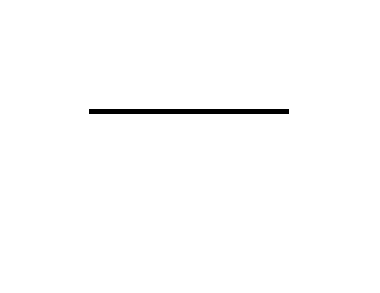

imshow(images(:,:,2), 'InitialMagnification', 500)

ys=[1,0; 0,1];

% X = reshape(1:64,8,8)';
% K = reshape(1:9,3,3)';
% theta = [1:4]';
% stride = 3;
% y=0;
% 
% [obj,d_K,d_theta]=CNN_gradient(X,y,Ks,stride,theta,'logistic','log likelihood')


Q2

disp('Q2')    

Q2


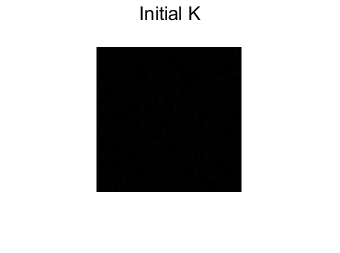

activation_fun = 'linear';
obj_fun = 'square error';
stride = 1;
K_M = 40; % width of kernel 
K_N = 1; % numbe of kernel
seed_num = 198;
rate = -.0000001;  % negative means minimization
alpha = 0.0000001; % L2 regularization
scale = 100;

Ks = zeros(K_M,K_M,K_N);
for ii=1:K_N
  rng(seed_num+ii)        
  % option 1
   temp = rand(K_M)/scale;      
  % option 2
%   temp = randi([-10,10],K_M,K_M)/scale;            
  Ks(:,:,ii) = temp;

end
[H,~] = size(images(:,:,1));
theta = rand(((H-K_M+1)/stride)^2*K_N,size(ys,2))/scale;
    
figure()
for kk = 1:K_N
    subplot(sqrt(K_N),sqrt(K_N),kk)
    imshow(Ks(:,:,kk), 'InitialMagnification', K_M*10)
end
suptitle('Initial K')

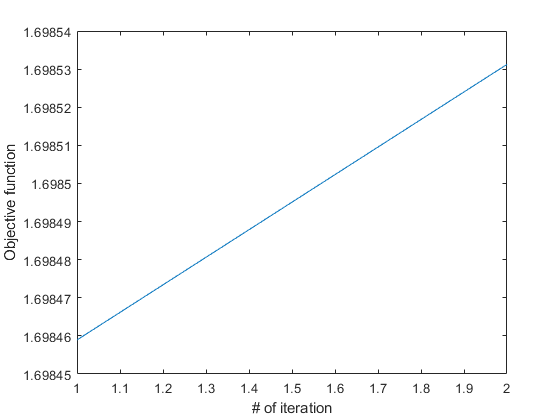

    
[Ks,theta]=CNNs(images,ys,Ks,theta,stride,activation_fun,obj_fun,rate,alpha);

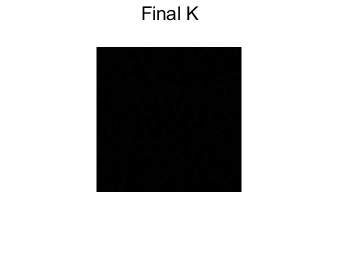

    % plot final Kernel
figure()
for kk = 1:K_N
    subplot(sqrt(K_N),sqrt(K_N),kk)
    imshow(Ks(:,:,kk), 'InitialMagnification', K_M*10)
end
suptitle('Final K')

Q3

disp('Q3')

Q3


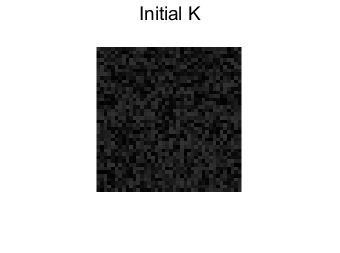

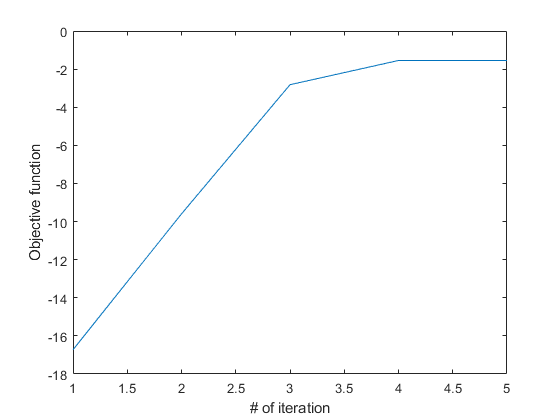

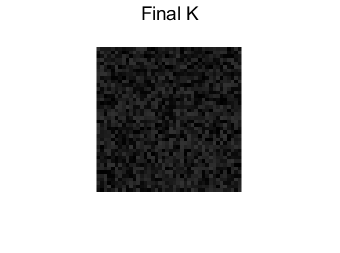

activation_fun = 'logistic';
obj_fun = 'log likelihood';
stride = 1;
K_M = 40; % width of kernel 
K_N = 1; % numbe of kernel

seed_num = 28;
rate = 0.0006;
alpha = 0.001;

[Ks,theta]=CNNs(images,ys,K_M,K_N,stride,activation_fun,obj_fun,seed_num,rate,alpha); 

disp('Q4')

Q4


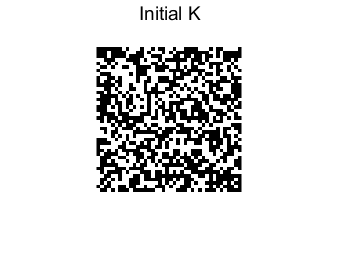

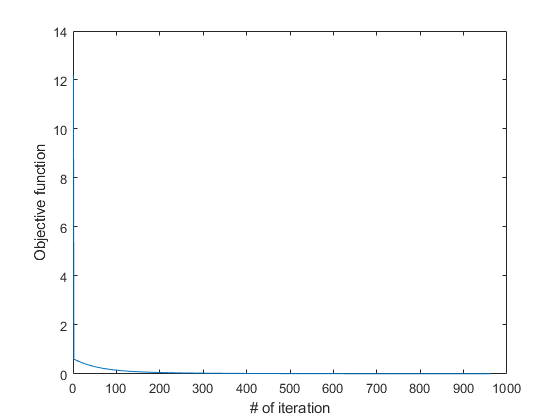

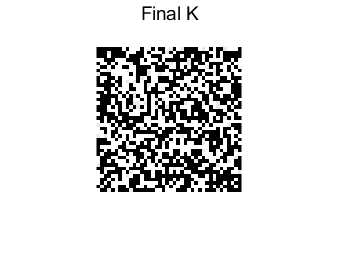

activation_fun = 'softmax';
obj_fun = 'cross entropy';
stride = 1;
K_M = 40; % width of kernel 
K_N = 1; % numbe of kernel

seed_num =1153;
rate = -0.01; % negative means minimization
alpha = 0.0001;

[Ks,theta]=CNNs(images,ys,K_M,K_N,stride,activation_fun,obj_fun,seed_num,rate,alpha); 

disp('Q5')

Q5


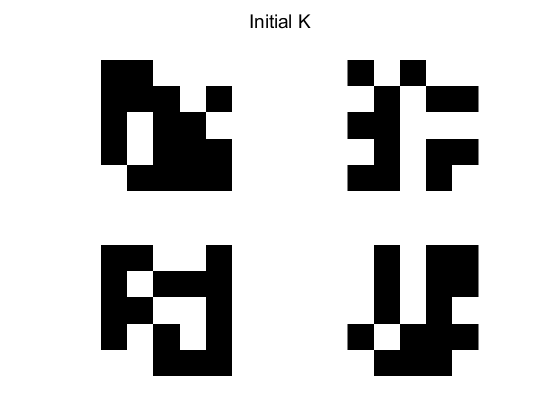

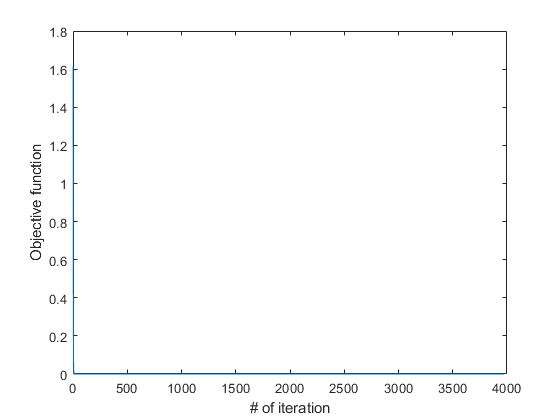

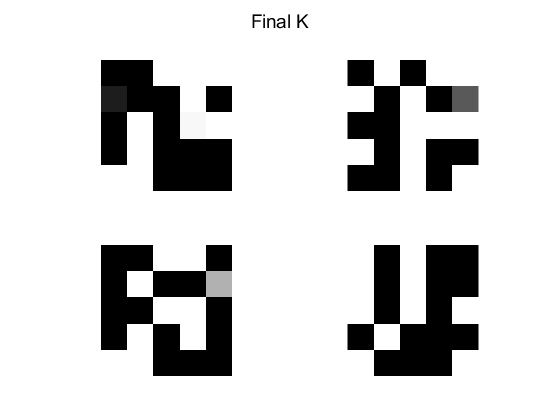

activation_fun = 'linear';
obj_fun = 'square error';
stride = 2;
K_M = 5; % width of kernel 
K_N = 4; % numbe of kernel

seed_num = 32;
rate = -0.01;
alpha = 0;

[Ks,theta]=CNNs(images,ys,K_M,K_N,stride,activation_fun,obj_fun,seed_num,rate,alpha); %#ok<*ASGLU> 

Q6 data read

[X_train,X_test,Y_train,Y_test]=data_read();

disp('Q6-config1')

Q6-config1


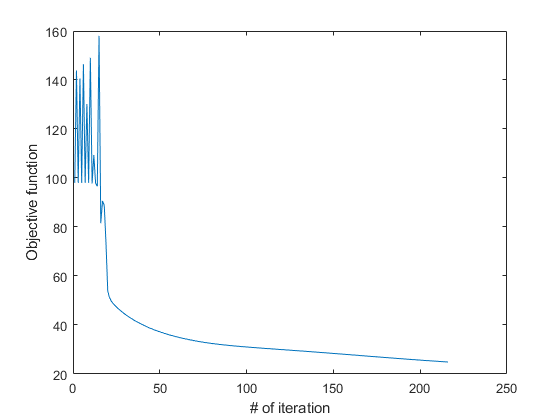

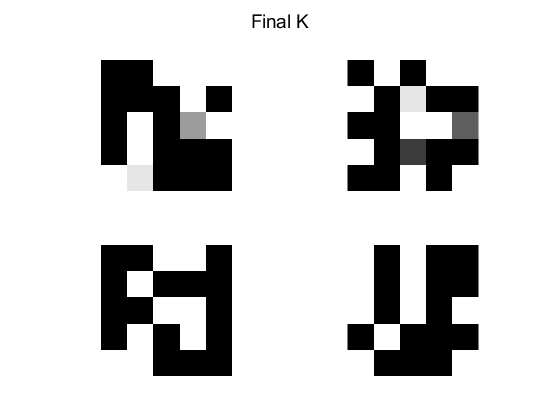

activation_fun = 'linear';
obj_fun = 'square error';
stride = 2;
K_M = 5; % width of kernel 
K_N = 4; % numbe of kernel

seed_num =32;
rate = -.00007;
alpha = .001;

% CNN
[Ks,theta]=CNNs(X_train,Y_train,K_M,K_N,stride,activation_fun,obj_fun,seed_num,rate,alpha); 


% train
[yp_train,train_accuracy]=CNN_eval(X_train,Y_train,Ks,stride,theta,activation_fun,obj_fun);
train_accuracy

train_accuracy = 1


% test
[yp_test,test_accuracy]=CNN_eval(X_test,Y_test,Ks,stride,theta,activation_fun,obj_fun);
test_accuracy

test_accuracy = 0.9286

disp('Q6-config2')

Q6-config2


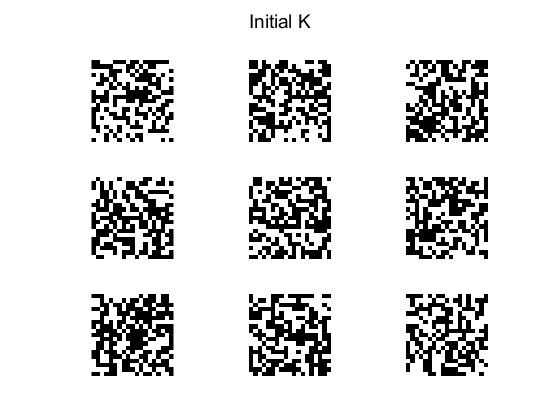

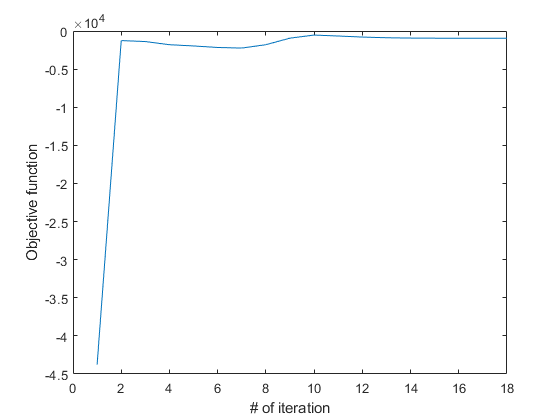

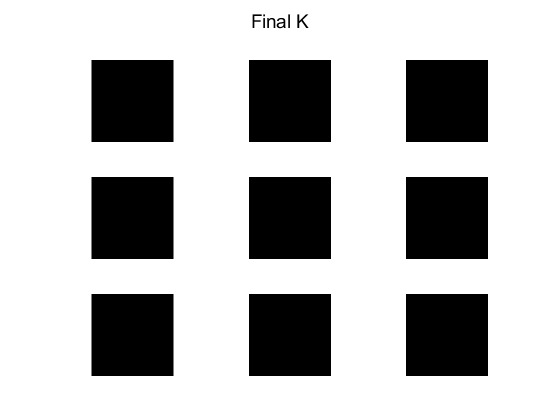

activation_fun = 'logistic';
obj_fun = 'log likelihood';
stride = 2;
K_M = 19; % width of kernel 
K_N = 9; % numbe of kernel

seed_num =354;
rate = 3e-7;
alpha = 0.5;

% CNN
[Ks,theta]=CNNs(X_train,Y_train,K_M,K_N,stride,activation_fun,obj_fun,seed_num,rate,alpha); 


% train
[yp_train,train_accuracy]=CNN_eval(X_train,Y_train,Ks,stride,theta,activation_fun,obj_fun);
train_accuracy

train_accuracy = 0.0816


% test
[yp_test,test_accuracy]=CNN_eval(X_test,Y_test,Ks,stride,theta,activation_fun,obj_fun);
test_accuracy

test_accuracy = 0.0714

function [yp,accuracy]=CNN_eval(X,Y,Ks,stride,theta,activation_fun,obj_fun)
    yp=zeros(size(Y));
    for ii=1:size(Y,1)
         [~,yp_ii,~,~] = CNN_forward(X(:,:,ii),Y(ii,:),Ks,stride,theta,activation_fun,obj_fun);
         yp(ii,:) = yp_ii;
    end

     M = confusionMatrix(yp,Y);
     
     accuracy = M(end,end) ;
     
end

function M = confusionMatrix(y_p,y_b)
    M = zeros(size(y_b,2)+1);
    for ii=1:size(y_p,1)
        y_p_b(ii,:) = y_p(ii,:)==max(y_p(ii,:));% choose a class for predicted value
        idx = find(y_b(ii,:)==1); % true class
        if y_p_b(ii,:)==y_b(ii,:)
            M(idx,idx) = M(idx,idx) +1;
        else
             idx_p = find(y_p_b(ii,:)==1);
             M(idx_p,idx) = M(idx_p,idx) +1;
        end  
    end
    % M = M/size(y_b,1); % get the percentage
    for jj=1:size(y_b,2)
        M(jj,end) = M(jj,jj)/sum(M(jj,1:end-1));
        M(end,jj) = M(jj,jj)/sum(M(1:end-1,jj));
    end
%     sum(diag(M(1:end-1,1:end-1)))/size(y_b,1)
    M(end,end) = sum(diag(M(1:end-1,1:end-1)))/sum(sum(M(1:end-1,1:end-1)));   
end